# Part 1: Separation vs. Isolation, physical interactions

In progress! Updated 12/2/2022 (line 236)

## 0. Indices 

rat_adc_ind = intersect(ya_ind, rat_ind);
[u_pairs_rc, ia_rat, ic_rat] = unique(rdb.paircode(rat_adc_ind));
parfind_rc = cell(length(u_pairs_rc),1);
 for i = 1:length(u_pairs_rc)
     parfind_rc{i} = intersect(find(rdb.paircode == u_pairs_rc(i)), ya_ind);
 end
 
 % Adults--no longer using
 rat_adt_ind = intersect(oa_ind, rat_ind);
[u_pairs_rt, ia_rat, ic_rat] = unique(rdb.paircode(rat_adt_ind));
parfind_rt = cell(length(u_pairs_rt),1);
 for i = 1:length(u_pairs_rt)
     parfind_rt{i} = intersect(find(rdb.paircode == u_pairs_rt(i)), oa_ind);
 end

 u_pairs = u_pairs_rc;

betypes = [-1 1 2 3 5 4];
 behaves2use = 1:5;
  behaviortypes = {'wrestling' 'mounting' 'grooming' 'rear-sniffing' 'face-to-face' 'body-sniffing' 'huddling'};
 phystypes = betypes; %might have used wrong variable name so this is just a catch 
 

## I. Physical interactions, total time

### A. Physical interactions, combined

 u_pairs = u_pairs_rc;
 parfind = parfind_rc;

 septime_mat = nan(length(u_pairs),length(cofind),length(betypes));
 septime_new = nan(length(u_pairs), length(cofind), length(betypes_n));
 for i = 1:size(u_pairs,1)
     for j = 1:length(cofind)
         curind = intersect(parfind{i}, cofind{j});
         if ~isempty(curind)
             septime_mat(i,j,1:length(betypes)) = sumbehav(curind,:);
             septime_new(i,j,1:length(betypes_n)) = sumbehav_new(curind,:);
         end
     end
 end

 septime_new = cat(3, septime_new, septime_mat(:,:,2:end));
       

Figure of total physical interaction data



stm_all = nansum(septime_mat(:,:,behaves2use),3);
stm_all(stm_all == 0) = nan; % all sessions have at least one behavior

% not normalized:
f = figure

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 544 560 420]
       Units: 'pixels'

  Show all properties


f2A = get(figure, 'Children')

f2A =   0×0 empty GraphicsPlaceholder array.


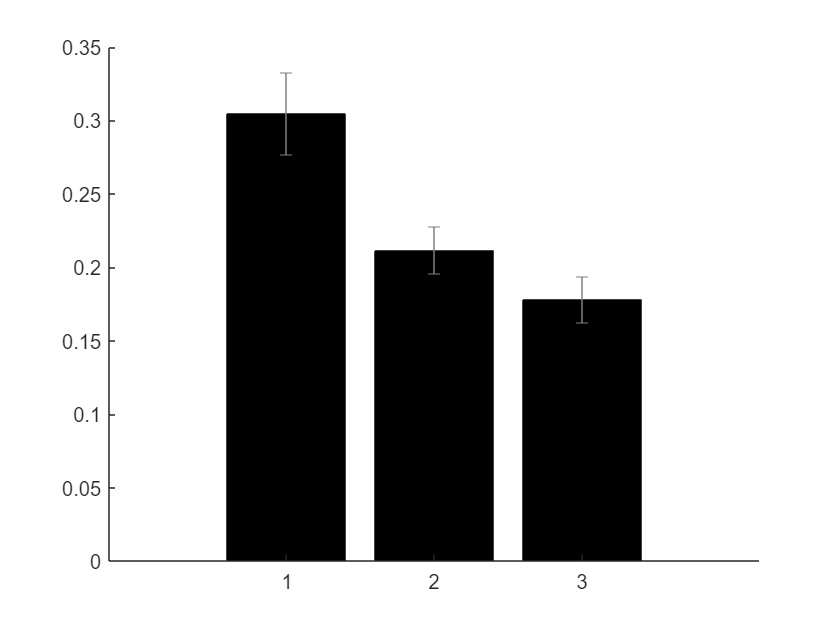

%    f2A = subplot(1,2,);
    bar(1:3, nanmean(stm_all), 'FaceColor', 'k');
    hold on;
    eb = errorbar(1:3, nanmean(stm_all), nanstd(stm_all)/sqrt(length(find(~isnan(stm_all(:,1))))-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
    set(f2A, 'XTickLabel', xticklabels);
    set(get(f2A, 'XLabel'), 'String', 'condition');
    set(get(f2A, 'YLabel'), 'String', 'proportion of time');
    set(get(f2A, 'Title'), 'String', 'All Physical Interactions');
    box off

**Bar graph showing the proportion of the 20 min reunion sessions that rats spent interacting after each of three conditions (ISO = 24 h social isolation, SEP = 24 h peer separation, CTL = 1 min isolation control). Interactions were higher following ISO compared with other manipulations.**

tbl = simple_mixed_anova(stm_all.^(1/3), [], {'exp_cond'})

tbl = 4×8 table
                             SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                            ________    __    _________    ______    __________    __________    __________    __________

    (Intercept)                13.14     1        13.14    1845.9    1.3236e-13    1.3236e-13    1.3236e-13    1.3236e-13
    Error                   0.078304    11    0.0071185                                                                  
    (Intercept):exp_cond    0.070776     2     0.035388    12.232    0.00026819     0.0010067    0.00055588     0.0049933
    Error(exp_cond)          0.06

%Partial eta squared = SSeffect / (SSeffect + SSerror)

The p-value for the effect of condition:

tbl.pValue(3)

ans = 2.6819e-04

The F value for condition:

tbl.F(3)

ans = 12.2316

The partial eta squared:

part_eta_square = tbl.SumSq(3) / (tbl.SumSq(3)+tbl.SumSq(4))

part_eta_square = 0.5265

Post-hoc t-tests to compared pairs of conditions:

%[p2, table] = anova_rm(stm_all);
 

 [a b] = ttest(stm_all(:,2)-stm_all(:,3))

a = 0

b = 0.0912

[a b] = ttest(stm_all(:,1)-stm_all(:,3))

a = 1

b = 9.1012e-04

 [a b] = ttest(stm_all(:,1)-stm_all(:,2))

a = 1

b = 0.0026

### B. Physical interaction types

Effects of different conditions on specific behaviors:

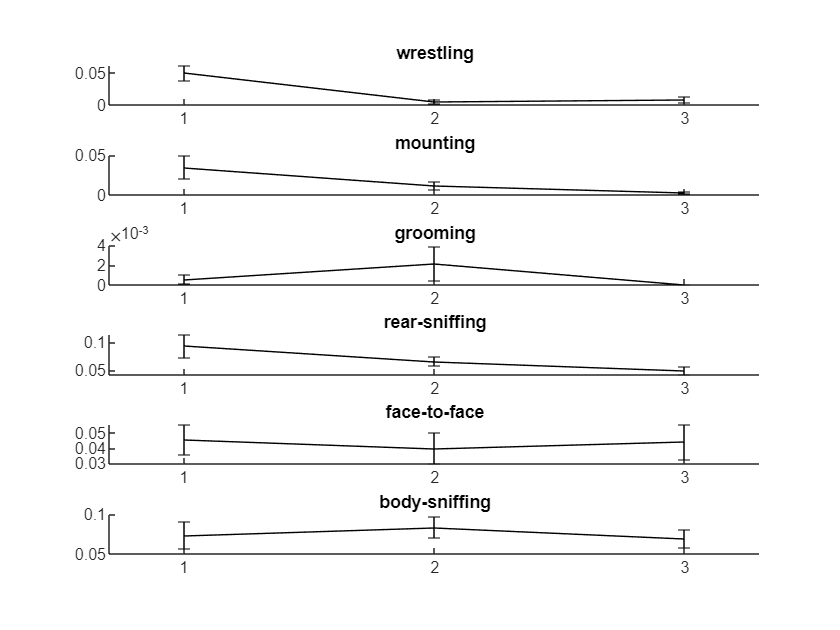

behaves2use = 1:6;

figure
 for i = 1:length(behaves2use)
%     f2B = subplot(4,3,i*3);
    f2B = subplot(length(behaves2use),1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septime_new(:,:,i)), nanstd(septime_new(:,:,i))/sqrt(length(find(~isnan(septime_new(:,1,i))))-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

 behaves2use = [1:6];
 f2B = cell(6,1);
 t = cell(6,1);
%figure
 for j = 1:length(behaves2use)

%         fprintf('species: %d, behavior: %d', i, j);
% % not normalized:
%         f2B{j} = subplot(length(behaves2use),1,j);
%         bar(1:3, nanmean(septime_mat(:,:,j)), 'FaceColor', 'k');
%         hold on;
%         eb = errorbar(1:3, nanmean(septime_mat(:,:,j)), nanstd(septime_mat(:,:,j))/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
%         set(f2B{j}, 'XTickLabel', xticklabels);
%         if j == length(behaves2use)
%             set(get(f2B{j}, 'XLabel'), 'String', 'condition');
%         end
%         if j == 3
%             set(get(f2B{j}, 'YLabel'), 'String', 'proportion of time');
% %        set(get(f2B{i,j}, 'Title'), 'String', 'All Physical Interactions');
%         end
%         box off

  
        t{j} = simple_mixed_anova(septime_new(:,:,j).^(1/3), [], {'exp_cond'});
%effect size:
        p_e_s(j) = t{j}.SumSq(3) / (t{j}.SumSq(3)+t{j}.SumSq(4));

%t-tests
        [a_is(j), b_is(j)] = ttest(septime_new(:,1,j).^(1/3) - septime_new(:,2,j).^(1/3)) ;
        co_d_is(j) = (nanmean(septime_new(:,1,j).^(1/3)) - nanmean(septime_new(:,2,j).^(1/3)))/nanstd([septime_new(:,1,j).^(1/3) ; septime_new(:,2,j).^(1/3)]);
       [a_ic(j), b_ic(j)] = ttest(septime_new(:,1,j).^(1/3) - septime_new(:,3,j).^(1/3)) ;
       co_d_ic(j) = (nanmean(septime_new(:,1,j).^(1/3)) - nanmean(septime_new(:,3,j).^(1/3)))/nanstd([septime_new(:,1,j).^(1/3) ; septime_new(:,3,j).^(1/3)]);
        [a_sc(j), b_sc(j)] = ttest(septime_new(:,2,j).^(1/3) - septime_new(:,3,j).^(1/3)) ;
        co_d_sc(j) = (nanmean(septime_new(:,2,j).^(1/3)) - nanmean(septime_new(:,3,j).^(1/3)))/nanstd([septime_new(:,2,j).^(1/3) ; septime_new(:,3,j).^(1/3)]);

%         stm = [septime_mat(:,:,j) ; septime_mat(:,:,j)];
%         tmp = simple_mixed_anova(stm.^(1/3), [ones(13,1); zeros(10,1)], {'exp_cond'}, {'species'})
%         tblB{j} = tmp;
 end
 for j = 1:length(behaves2use)
     fprintf('behavior: %s', behaviortypes{j});
     t{j}
 end 

behavior: wrestling

ans = 4×8 table
                             SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                            _______    __    ________    ______    __________    __________    __________    __________

    (Intercept)              1.0552     1      1.0552    34.201    0.00011119    0.00011119    0.00011119    0.00011119
    Error                   0.33939    11    0.030854                                                                  
    (Intercept):exp_cond    0.36901     2      0.1845    14.321    0.00010399    0.00018187    0.00010399     0.0030243
    Error(exp_cond)         0.28343    22  

behavior: mounting

ans = 4×8 table
                             SumSq      DF     MeanSq       F        pValue      pValueGG     pValueHF     pValueLB 
                            ________    __    ________    ______    _________    _________    _________    _________

    (Intercept)              0.78582     1     0.78582    13.717    0.0034794    0.0034794    0.0034794    0.0034794
    Error                    0.63016    11    0.057288                                                              
    (Intercept):exp_cond    0.062941     2     0.03147    3.0729     0.066541     0.098062     0.095142      0.10739
    Error(exp_cond)           0.2253    22    0.010241    

behavior: grooming

ans = 4×8 table
                              SumSq      DF     MeanSq        F        pValue     pValueGG    pValueHF    pValueLB
                            _________    __    _________    ______    ________    ________    ________    ________

    (Intercept)              0.016303     1     0.016303    5.0488    0.046136    0.046136    0.046136    0.046136
    Error                     0.03552    11    0.0032291                                                          
    (Intercept):exp_cond    0.0089842     2    0.0044921     1.044     0.36885     0.34789     0.35291     0.32884
    Error(exp_cond)          0.094663    22    0.0043029            

behavior: rear-sniffing

ans = 4×8 table
                             SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                            ________    __    _________    ______    __________    __________    __________    __________

    (Intercept)                5.423     1        5.423    458.74    2.5597e-10    2.5597e-10    2.5597e-10    2.5597e-10
    Error                    0.13004    11     0.011821                                                                  
    (Intercept):exp_cond    0.027549     2     0.013775     2.838      0.080075      0.097667      0.090176       0.12018
    Error(exp_cond)          0.10

behavior: face-to-face

ans = 4×8 table
                              SumSq      DF     MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                            _________    __    _________    _______    __________    __________    __________    __________

    (Intercept)                3.5417     1       3.5417     102.31    6.5955e-07    6.5955e-07    6.5955e-07    6.5955e-07
    Error                     0.38079    11     0.034617                                                                   
    (Intercept):exp_cond    0.0033184     2    0.0016592    0.96684       0.39586       0.39472       0.39586        0.3466
    Error(exp_cond)     

behavior: body-sniffing

ans = 4×8 table
                              SumSq      DF     MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                            _________    __    _________    _______    __________    __________    __________    __________

    (Intercept)                6.0136     1       6.0136     345.68    1.1676e-09    1.1676e-09    1.1676e-09    1.1676e-09
    Error                     0.19136    11     0.017397                                                                   
    (Intercept):exp_cond    0.0041735     2    0.0020867    0.67634       0.51873       0.49635       0.51598       0.42832
    Error(exp_cond)     

P-values for iso-sep, iso-ctl, and sep-ctl

 b_is

b_is =     0.0017    0.1182    0.7365    0.4140    0.2184    0.1766


 b_ic

b_ic =     0.0005    0.0936    0.1659    0.0392    0.3498    0.9181


 b_sc

b_sc =     0.9378    0.1650    0.1742    0.0546    0.4468    0.4509


Effect size for full model:

 p_e_s

p_e_s =     0.5656    0.2184    0.0867    0.2051    0.0808    0.0579


Effect size for pairwise comparisons

 co_d_is

co_d_is =     1.2332    0.2457   -0.1858    0.3719    0.2969   -0.3134


 co_d_ic

co_d_ic =     1.1090    0.5500    0.5655    0.7450    0.1473   -0.0292


 co_d_sc

co_d_sc =    -0.1633    0.4039    0.5906    0.5508   -0.1464    0.3322


## II. Physical interactions over time

### A. All behaviors

% A.Cumulative activity over time
cumsumbehav = Rdb_CumSum2(rdb, betypes(1:5), 1);

csum = sum(cumsumbehav, 3);

 cumsum_f_a_d1 = nan(length(u_pairs), 601, length(cofind));
h_cs_f_a = nan(length(u_pairs), length(cofind));
 
 for k = 1:length(cofind)
    for i = 1:size(u_pairs,1)
        
        curind = intersect(find(rdb.paircode == u_pairs(i)), cofind{k});
        if ~isempty(curind)
            cumsum_f_a_d1(i,:,k) = csum(curind,:);
        %    h_cs_f_a(i,k) = csum_ht(curind);
        end
        
    end
 end

Display cumsums

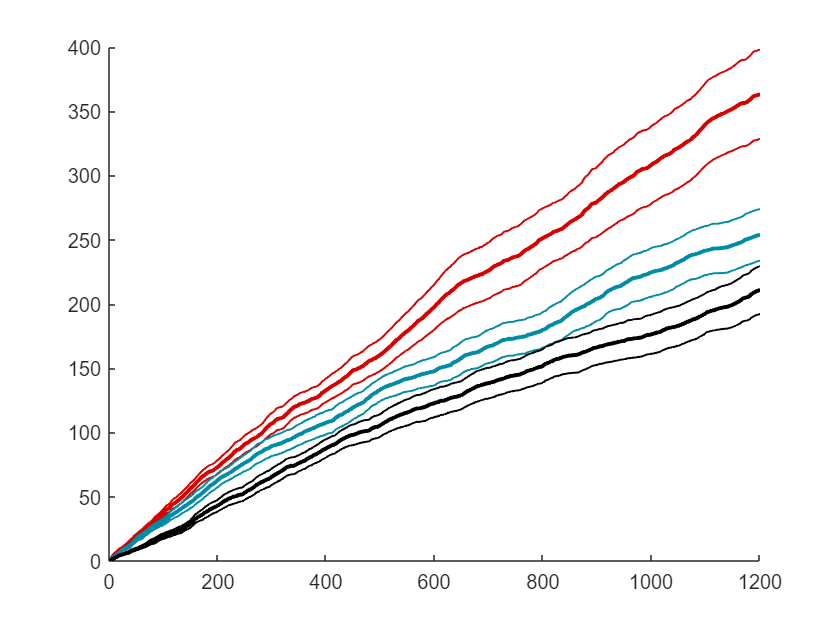

 figure
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'k:');
% hold on
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'k--');
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'k-');
% 

errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(find(~isnan(cumsum_f_a_d1(:,20,1))))-1), 'Color', [.85 0 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(find(~isnan(cumsum_f_a_d1(:,20,2))))-1), 'Color', [0 .55 .65]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(find(~isnan(cumsum_f_a_d1(:,20,3))))-1), 'Color', [0 0 0]);

box off

Same figure, only first 5 minutes: 

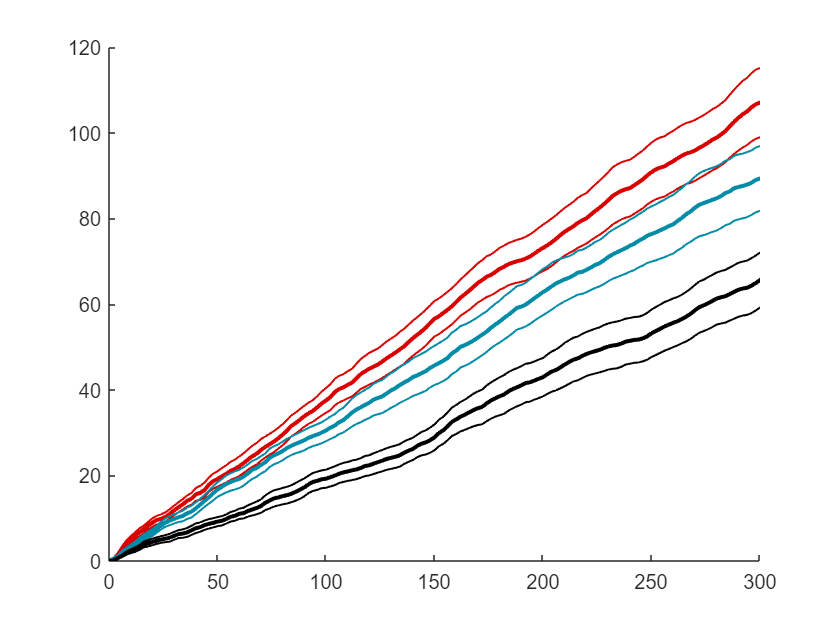

figure
e2 = errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(find(~isnan(cumsum_f_a_d1(:,20,1))))-1), 'Color', [.85 0 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(find(~isnan(cumsum_f_a_d1(:,20,2))))-1), 'Color', [0 .55 .65]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(find(~isnan(cumsum_f_a_d1(:,20,3))))-1), 'Color', [0 0 0]);
set(get(e2{1}, 'Parent'), 'XLim', [0 300]);
set(get(e2{1}, 'Parent'), 'YLim', [0 120]);


box off

Here we look at the pairwise comparisons at each time step (p-values and Cohen's d effect sizes):

for i = 1:length(cumsum_f_a_d1)

    [~, is_cumsum(i)] = ttest(cumsum_f_a_d1(:,i,1) - cumsum_f_a_d1(:,i,2));
    [~, ic_cumsum(i)] = ttest(cumsum_f_a_d1(:,i,1) - cumsum_f_a_d1(:,i,3));
    [~, sc_cumsum(i)] = ttest(cumsum_f_a_d1(:,i,2) - cumsum_f_a_d1(:,i,3));
    sc_cod(i) = (nanmean(cumsum_f_a_d1(:,i,2))-nanmean(cumsum_f_a_d1(:,i,3)))/nanstd([cumsum_f_a_d1(:,i,2) ; cumsum_f_a_d1(:,i,3)]);
end

sc_cumsum

sc_cumsum =        NaN    0.0645    0.3252    0.1003    0.0666    0.0662    0.1028    0.0788    0.1565    0.1687    0.1422    0.0816    0.0526    0.0450    0.0527    0.0523    0.0478    0.0563    0.0487    0.0630    0.0525    0.0260    0.0180    0.0121    0.0088    0.0045    0.0039    0.0043    0.0059    0.0076    0.0113    0.0095    0.0080    0.0066    0.0061    0.0052    0.0076    0.0066    0.0068    0.0070    0.0058    0.0044    0.0042    0.0052    0.0079    0.0086    0.0088    0.0090    0.0099    0.0094


[mn, loc] = min(sc_cumsum)

mn = 0.0018

loc = 125

sc_cod(loc)

ans = 1.0239

intsig = find(sc_cumsum < 0.01) * 2

intsig =     50    52    54    56    58    60    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100   102   104   106   108   110   112   114   116   118   120   122   124   126   128   130   132   134   136   138   140   142   144   146   148   150



length(find(sc_cod(15:150) > 1))/145

ans = 0.6000

length(find(sc_cumsum(15:150) < 0.005))/145

ans = 0.5034

### B. Individual behaviors over time

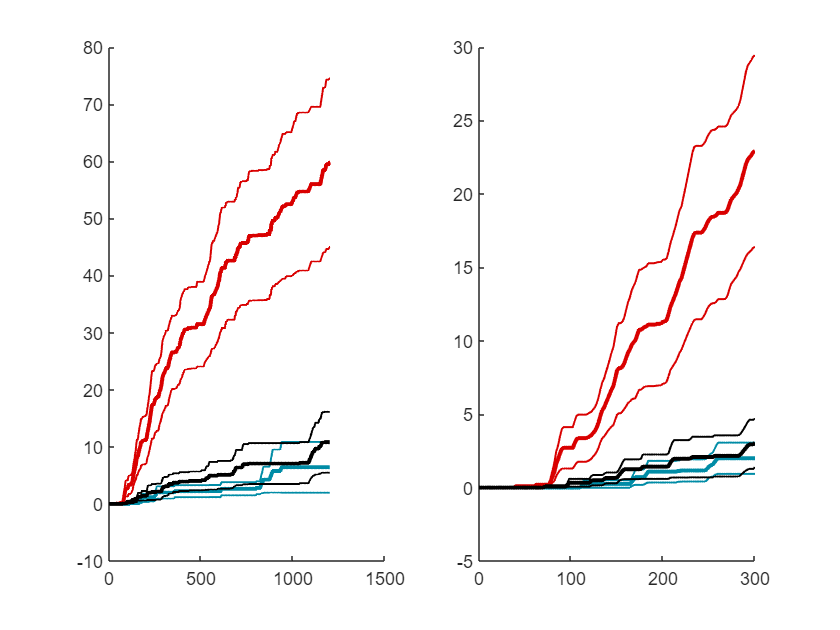

ans = 0.0034

ans = 1.1913

ans = 0.0015

ans = 5.1624

ans = 0.3129

ans = -0.4331

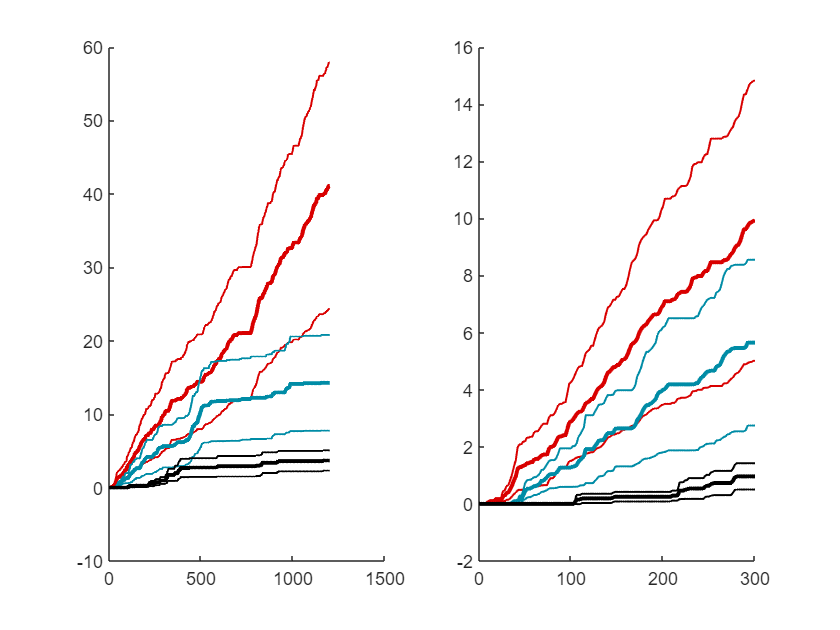

ans = 0.1738

ans = 0.2531

ans = 0.0527

ans = 1.0784

ans = 0.0660

ans = 0.6576

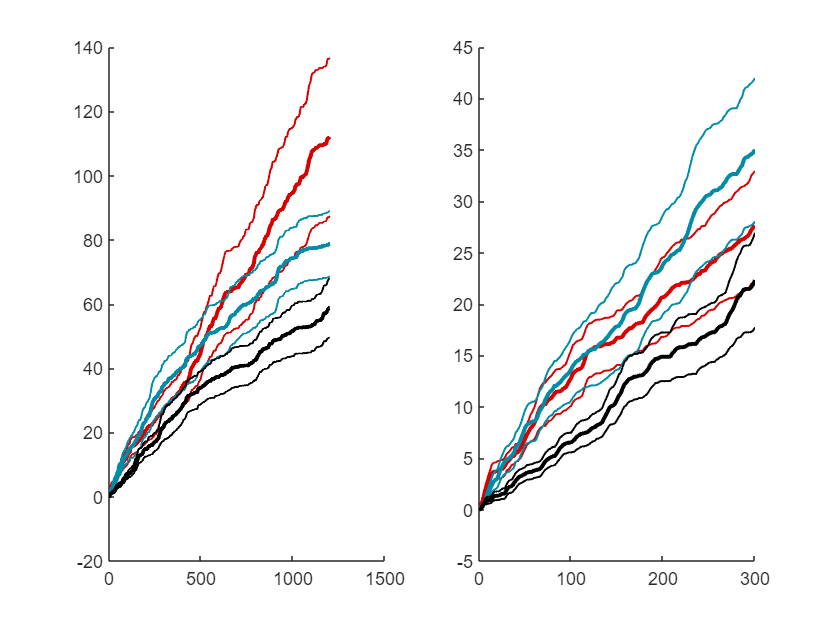

ans = 0.9353

ans = 0.1905

ans = 0.0729

ans = 0.8493

ans = 0.0394

ans = 0.5964

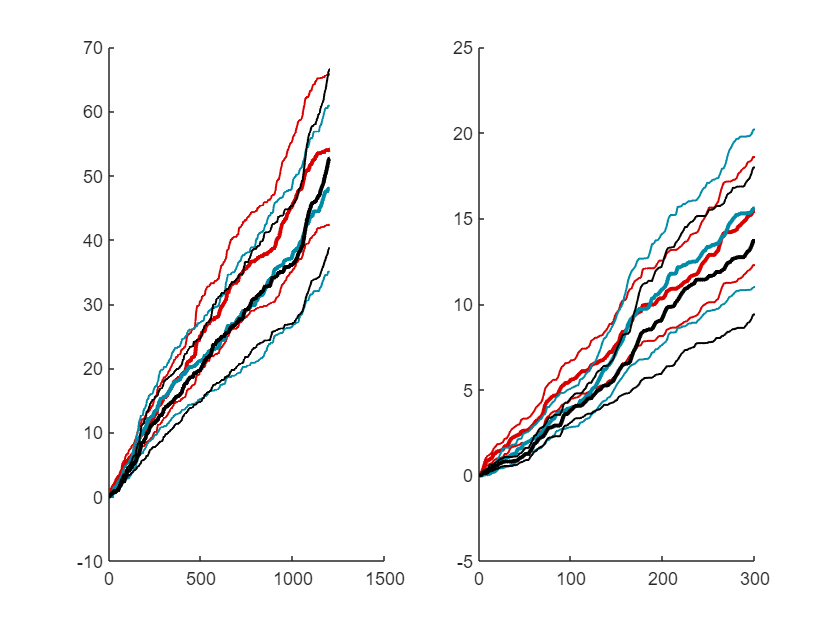

ans = 0.2053

ans = 0.2429

ans = 0.0799

ans = 0.1797

ans = 0.8252

ans = -0.0490

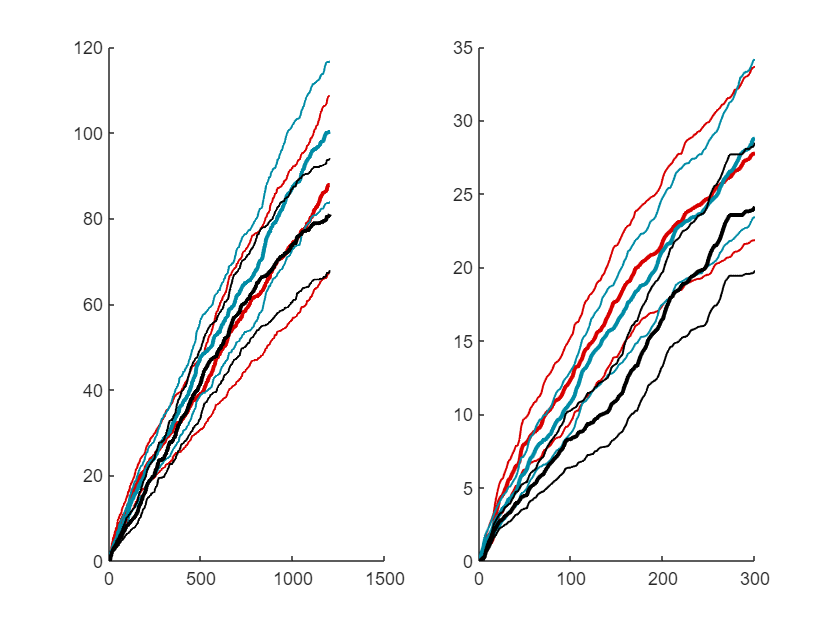

ans = 0.4498

ans = -0.1483

ans = 0.8989

ans = -0.0404

ans = 0.9124

ans = 0.1346

betypes_c = [-1.7 -1 2 3 5];

cumsumbehav = Rdb_CumSum2(rdb, betypes_c, 1);



cumsum_b = cell(length(betypes_c),1);
is_cumsum_b = cell(length(betypes_c),1);
ic_cumsum_b = cell(length(betypes_c),1);
sc_cumsum_b = cell(length(betypes_c),1);
is_cod_b = cell(length(betypes_c),1);
ic_cod_b = cell(length(betypes_c),1);
sc_cod_b = cell(length(betypes_c),1);




for j = 1:length(betypes_c)
     cumsum_b{j} = nan(length(u_pairs), 601, length(cofind));
    h_cs_f_a = nan(length(u_pairs), length(cofind));
 
     for k = 1:length(cofind)
        for i = 1:size(u_pairs,1)
        
            curind = intersect(find(rdb.paircode == u_pairs(i)), cofind{k});
            if ~isempty(curind)
                cumsum_b{j}(i,:,k) = cumsumbehav(curind,:,j);
           end
        
        end
     end
      figure
        % errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'k:');
        % hold on
        % errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'k--');
        % errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'k-');
        % 

        subplot(1,2,1)
        errorbar_alt(0:2:1200, nanmean(cumsum_b{j}(:, :, 1)), nanstd(cumsum_b{j}(:, :, 1))/sqrt(length(find(~isnan(cumsum_b{j}(:,20,1))))-1), 'Color', [.85 0 0]);
        hold on
        errorbar_alt(0:2:1200, nanmean(cumsum_b{j}(:, :, 2)), nanstd(cumsum_b{j}(:, :, 2))/sqrt(length(find(~isnan(cumsum_b{j}(:,20,2))))-1), 'Color', [0 .55 .65]);
        errorbar_alt(0:2:1200, nanmean(cumsum_b{j}(:, :, 3)), nanstd(cumsum_b{j}(:, :, 3))/sqrt(length(find(~isnan(cumsum_b{j}(:,20,3))))-1), 'Color', [0 0 0]);

        box off

        subplot(1,2,2)
        errorbar_alt(0:2:300, nanmean(cumsum_b{j}(:, 1:151, 1)), nanstd(cumsum_b{j}(:, 1:151, 1))/sqrt(length(find(~isnan(cumsum_b{j}(:,20,1))))-1), 'Color', [.85 0 0]);
        hold on
        errorbar_alt(0:2:300, nanmean(cumsum_b{j}(:, 1:151, 2)), nanstd(cumsum_b{j}(:, 1:151, 2))/sqrt(length(find(~isnan(cumsum_b{j}(:,20,2))))-1), 'Color', [0 .55 .65]);
        errorbar_alt(0:2:300, nanmean(cumsum_b{j}(:, 1:151, 3)), nanstd(cumsum_b{j}(:, 1:151, 3))/sqrt(length(find(~isnan(cumsum_b{j}(:,20,3))))-1), 'Color', [0 0 0]);

        box off

        

        for i = 1:length(cumsum_f_a_d1)

            [~, is_cumsum_b{j}(i)] = ttest(cumsum_b{j}(:,i,1) - cumsum_b{j}(:,i,2));
            is_cod_b{j}(i) = (nanmean(cumsum_b{j}(:,i,1))-nanmean(cumsum_b{j}(:,i,2)))/nanstd([cumsum_b{j}(:,i,1) ; cumsum_b{j}(:,i,2)]);
            [~, ic_cumsum_b{j}(i)] = ttest(cumsum_b{j}(:,i,1) - cumsum_b{j}(:,i,3));
            ic_cod_b{j}(i) = (nanmean(cumsum_b{j}(:,i,1))-nanmean(cumsum_b{j}(:,i,3)))/nanstd([cumsum_b{j}(:,i,2) ; cumsum_b{j}(:,i,3)]);
            [~, sc_cumsum_b{j}(i)] = ttest(cumsum_b{j}(:,i,2) - cumsum_b{j}(:,i,3));
            sc_cod_b{j}(i) = (nanmean(cumsum_b{j}(:,i,2))-nanmean(cumsum_b{j}(:,i,3)))/nanstd([cumsum_b{j}(:,i,2) ; cumsum_b{j}(:,i,3)]);
        end
       
        is_cumsum_b{j}(300)
        is_cod_b{j}(300)
        ic_cumsum_b{j}(300)
        ic_cod_b{j}(300)
        sc_cumsum_b{j}(300)
        sc_cod_b{j}(300)
       
end

#### Ratio of mounting to playing (not included in paper, but interesting differences)

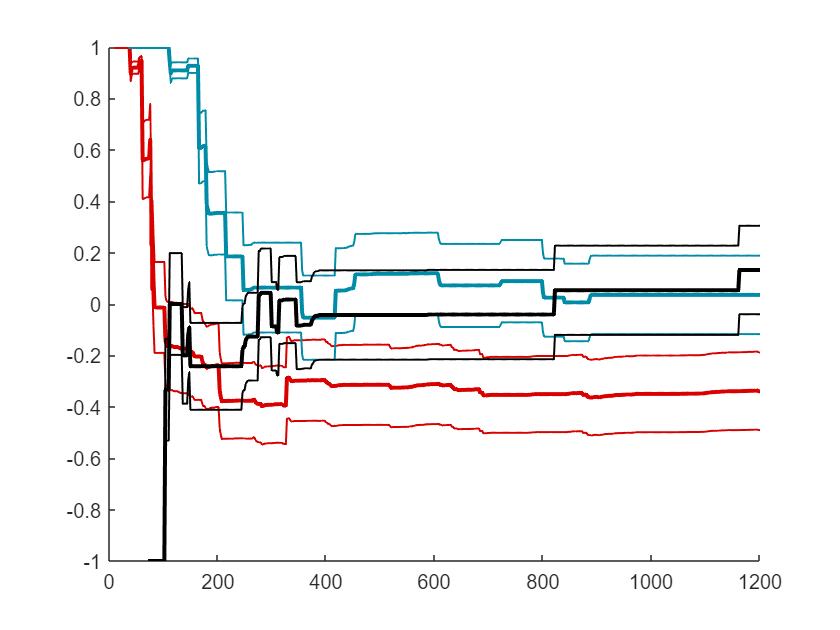

cumsum_m2p = (cumsum_b{2}-cumsum_b{1})./(cumsum_b{2} + cumsum_b{1});    

figure
errorbar_alt(0:2:1200, nanmean(cumsum_m2p(:, :, 1)), nanstd(cumsum_m2p(:, :, 1))/sqrt(length(u_pairs)-1), 'Color', [.85 0 0]);
        hold on
        errorbar_alt(0:2:1200, nanmean(cumsum_m2p(:, :, 2)), nanstd(cumsum_m2p(:, :, 2))/sqrt(length(u_pairs)-1), 'Color', [0 .55 .65]);
        errorbar_alt(0:2:1200, nanmean(cumsum_m2p(:, :, 3)), nanstd(cumsum_m2p(:, :, 3))/sqrt(length(u_pairs)-1), 'Color', [0 0 0]);

        box off

## III. Repeat Part I in full adults (no longer including: insufficient data)

        
u_pairs = u_pairs_rt;
parfind = parfind_rt;

    septime_mat_a = nan(length(u_pairs),length(cofind),length(betypes));
    septime_new_a = nan(length(u_pairs), length(cofind), length(betypes_n));
        for i = 1:size(u_pairs,1)
            for j = 1:length(cofind)
                curind = intersect(parfind{i}, cofind{j});
                if ~isempty(curind)
                    septime_mat_a(i,j,1:length(betypes)) = sumbehav(curind,:);
                    septime_new_a(i,j,1:length(betypes_n)) = sumbehav_new(curind,:);
                end
            end
        end

        septime_new_a = cat(3, septime_new_a, septime_mat_a(:,:,2:end));

        

        stm_all_a = nansum(septime_mat_a(:,:,behaves2use),3);
    stm_all_a(stm_all_a == 0) = nan;
 
% not normalized:
f = figure

f =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 544 560 420]
       Units: 'pixels'

  Show all properties


f2A = get(figure, 'Children')

f2A =   0×0 empty GraphicsPlaceholder array.


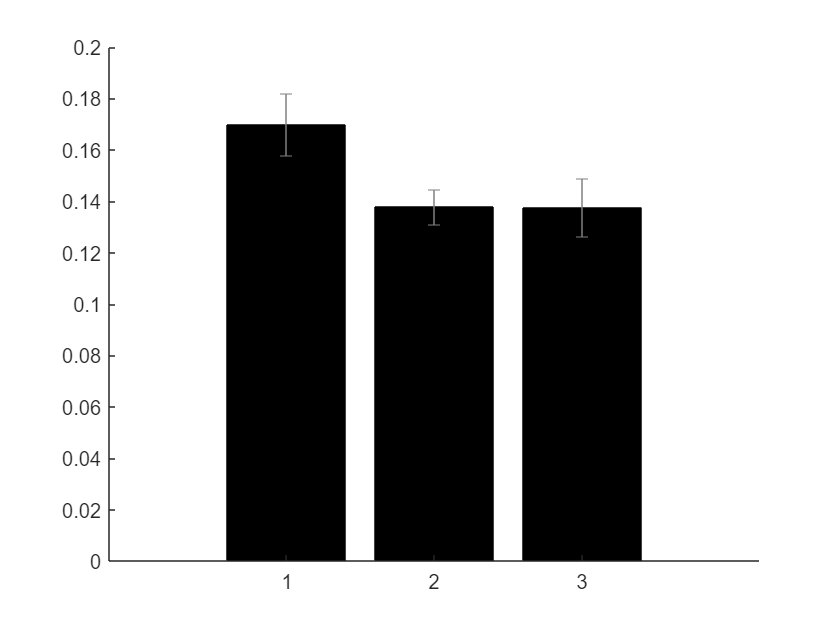

%    f2A = subplot(1,2,);
    bar(1:3, nanmean(stm_all_a), 'FaceColor', 'k');
    hold on;
    eb = errorbar(1:3, nanmean(stm_all_a), nanstd(stm_all_a)/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
    set(f2A, 'XTickLabel', xticklabels);
    set(get(f2A, 'XLabel'), 'String', 'condition');
    set(get(f2A, 'YLabel'), 'String', 'proportion of time');
    set(get(f2A, 'Title'), 'String', 'All Physical Interactions');
    box off

tbl = 4×8 table
                              SumSq      DF     MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                            _________    __    _________    _______    __________    __________    __________    __________

    (Intercept)                3.2582    1        3.2582     374.04    0.00030194    0.00030194    0.00030194    0.00030194
    Error                    0.026133    3     0.0087108                                                                   
    (Intercept):exp_cond    0.0033785    2     0.0016893    0.42838       0.67003       0.60511       0.67003       0.55949
    Error(exp_cond)     

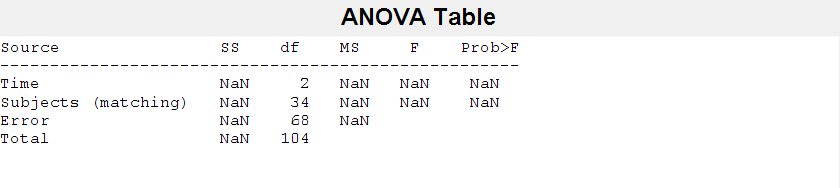

 
    maxy = get(f2A, 'YLim');


tbl = simple_mixed_anova(stm_all_a.^(1/3), [], {'exp_cond'})

 
 [a b] = ttest(stm_all_a(:,2)-stm_all_a(:,3))

a = 0

b = 0.9958

[a b] = ttest(stm_all_a(:,1)-stm_all_a(:,3))

a = 0

b = 0.3853

 [a b] = ttest(stm_all_a(:,1)-stm_all_a(:,2))

a = 0

b = 0.5281

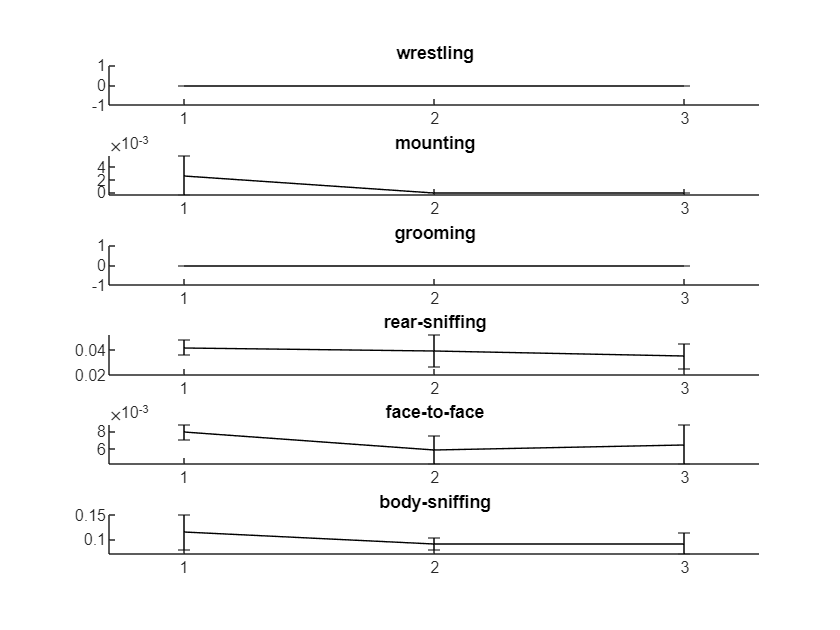

 behaves2use = 1:6;

figure
 for i = 1:length(behaves2use)
%     f2B = subplot(4,3,i*3);
    f2B = subplot(length(behaves2use),1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septime_new_a(:,:,i)), nanstd(septime_new_a(:,:,i))/sqrt(size(septime_new_a,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

## IV: Vocalizations (no longer using -- insufficient data across condition types)

Rather than re-doing this several times, let's make the sepvoctime_mat

out of whichever variable we are most interested at the moment

options are:

sumvoc -- all syllables

nsumvoc -- all syllables, exclusing nans

csumvoc -- syllables combined into "calls"

rsumvoc -- the rate of syllables, rather than the proportion of time (number instead of time) 

%

### A. summed vocalizations

%A lot of this code comes directly from reunionOTRA2.mlx

% sv = rsumvoc; %plug in another option, depending on interest

Unrecognized function or variable 'rsumvoc'.

% 
%  sepvoctime_mat = nan(length(u_pairs),length(cofind));
%  vocnum_mat = sepvoctime_mat;
% % svt_4 = nan(length(u_paircodes),3,2);
% % side_svt = svt_4;
% 
%  for i = 1:length(u_pairs)
%      for k = 1:length(cofind)
%          curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});
%          sepvoctime_mat(i, k) = sv(curind,:);    
%          vocnum_mat(i, k) = nsumvoc(curind,:); %this is a weird way to jump back to the voc nums, but moving on 
%      end
%  end

% f = figure
%  curmat = sepvoctime_mat;
% %curmat = vocnum_mat;
% 
%  bar(nanmean(curmat), 'k')
% hold on
% errorbar(1:3, nanmean(curmat), nanstd(curmat)/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
% box off
% set(get(f, 'Children'), 'XTick', [1:3])
% set(get(f, 'Children'), 'XTickLabel', xticklabels);

% p = anova_rm(sepvoctime_mat);
% p = anova_rm(vocnum_mat);

### B Vocalizations by type

% sv = rvoc;
% 
% sepvoctime_mat_full = nan(length(u_pairs), length(cofind), length(indvocsgood));
% 
%  for i = 1:length(u_pairs)
%      for k = 1:length(cofind)
%         curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});
% 
%          sepvoctime_mat_full(i, k, :) = sv(curind,:);    
%      end
%  end

Figures

%  f4 = figure;
% 
% 
%  hold on
% b1 = bar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', 'BarWidth', .15, 'FaceColor', [.85 0 0 ]);
% b2 = bar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', 'BarWidth', .15, 'FaceColor', [0 .55 .65]);
% b3 = bar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:)))', 'BarWidth', .15, 'FaceColor', [0 0 0]);
% e1 = errorbar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
% e2 = errorbar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
% e3 = errorbar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:) )), squeeze(nanstd(sepvoctime_mat_full(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
% %bar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), 'BarWidth', .35);
% %errorbar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), squeeze(nanstd(voctime_mat(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none');
% set(get(f4, 'Children'), 'XTickMode', 'manual')
% set(get(f4, 'Children'), 'XTick', 1:15)
% ivg = indvocsgood; %([1:6 8:end]);
% set(get(f4, 'Children'), 'XTickLabel', rdb.voctypes(ivg))
% set(get(f4, 'Children'), 'XTickLabelRotation', 60)

%  sVM_chit = sepvoctime_mat_full(:,:,5);
%  sVM_nc = nansum(sepvoctime_mat_full(:,:,[1:4 6:end]), 3)
%  nc2c = sVM_nc./sVM_chit;
%  [a b] = ranksum(nc2c(:,2), nc2c(:,1));
%  

% 
% curmat = sepvoctime_mat_full;
% 
% s = size(curmat);
% 
% toprowDM = cell(1,s(2)*s(3));
% idatamat = cell(s(2)*s(3),2);
% for i = 1:s(2)
%     for j = 1:s(3)
%         toprowDM{i+(j-1)*s(2)} = ['B' num2str(i) 'C' num2str(j)]; 
%         idatamat{i+(j-1)*s(2),1} = ['B' num2str(i)];
%         idatamat{i+(j-1)*s(2),2} = ['C' num2str(j)];
%     end
% end
% 
% datamat = num2cell(reshape(curmat, s(1), s(2)*s(3),1));
% full_dm = [[{'subject'} toprowDM] ; [num2cell([1:size(datamat,1)]') datamat]];
% T = cell2table(full_dm(2:end,:), 'VariableNames', full_dm(1,:));
% writetable(T,'datamat.csv');

To do the stats, need to be running R

%!C:\Program Files\R\R-3.6.1\bin\x64\Rscript

% full_idm = [{'B' 'C'} ; idatamat];
% iT = cell2table(full_idm(2:end,:), 'VariableNames', full_idm(1,:));
% writetable(iT,'idatamat.csv');

%  s = sepvoctime_mat_full(:,1:3,:);
%  be = ones(size(s));
%  for i = 1:size(s,3)
%      be(:,:,i) = i;
%  end
%  cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
%  
%  sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
%  br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
%  cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
%  
%  
%  [p t s] = anovan(sr, [br cr], 'model', 'interaction');

### C Automated clustering

#### 1. SEP vs. ISO

% inds = cell(9,2);
% conds = [1 2 3];
% 
% for i = 1:length(u_pairs)
%     for j = 1:3
%         curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{conds(j)});
%         inds{i,j} = find(indfeat_nn(:,1) == curind); 
% %        vip_inds{i,j} = intersect(inds{i,j}, vocind_best);
%     end
% end

% 

Assess significance of the clusters

% %[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[1 2]), 0, [], 9);
% %save isosep_sigclusts pvals_c ef_c val_c
% load isosep_sigclusts

% [isosep_prevocbest, isosep_vocindbest, isosep_irc, isosep_nm] = process_sigclusts(pvals_c, ef_c, val_c,  idx, indfeat_nn);
% isosep_nm

What are the features and manual classifications associated with the most differentially expressed vocalization?

% [h1, h2, h3, h4] = sigclust_Figures(isosep_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

% % 
% %  [maxef, ind_bestclustnum] = max(efmat(1,:));
% % spv = squeeze(pvals(:,ind_bestclustnum,:));
% % sev = squeeze(ef(:,ind_bestclustnum,:));
% % 
% % for i = 1:size(spv,2)
% %     rowmin2(i) = find(spv(:,i) == min(spv(:,i)));
% %     pvb2{i} = idx{ind_bestclustnum, i} == rowmin2(i);
% % end
% % 
% % curisig = nan(length(pvb2));
% % for i = 1:length(pvb2)
% %     for j = 1:length(pvb2)
% %         if i ~= j
% %             curisig(i,j) = rand_index(pvb2{i}, pvb2{j});
% %         end
% %         
% %     end
% % end
% % 
% % arisig = nanmean(nanmean(curisig));
% % % hold
% % % box off
% % % plot(20, arisig, 'r*')
% 
% 

% 

% 
% 
% 

#### 2.  ISO vs. CTL

% %[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[1 3]), 0, [], 9);
% %save iso2_sigclusts pvals_c ef_c val_c
% load iso2_sigclusts
% 
% [iso2_prevocbest, iso2_vocindbest, iso2_irc, iso2_nm] = process_sigclusts(pvals_c, ef_c, val_c,  idx, indfeat_nn);
% iso2_nm

What are the features and manual classifications associated with the most differentially expressed vocalization?

% [h1, h2, h3, h4] = sigclust_Figures(iso2_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

% % 
% %  [maxef, ind_bestclustnum] = max(efmat(1,:));
% % spv = squeeze(pvals(:,ind_bestclustnum,:));
% % sev = squeeze(ef(:,ind_bestclustnum,:));
% % 
% % for i = 1:size(spv,2)
% %     rowmin2(i) = find(spv(:,i) == min(spv(:,i)));
% %     pvb2{i} = idx{ind_bestclustnum, i} == rowmin2(i);
% % end
% % 
% % curisig = nan(length(pvb2));
% % for i = 1:length(pvb2)
% %     for j = 1:length(pvb2)
% %         if i ~= j
% %             curisig(i,j) = rand_index(pvb2{i}, pvb2{j});
% %         end
% %         
% %     end
% % end
% % 
% % arisig = nanmean(nanmean(curisig));
% % % hold
% % % box off
% % % plot(20, arisig, 'r*')

### 3 Cross-examine clusters across 3 comparisons

% % isosep_prevocbest;
% % isosep_vocindbest;
% % iso_prevocind;
% % iso_vocind;
% % iso2_prevocind;
% % iso2_vocind;
% 
% %
% 
% length(intersect(isosep_prevocbest{1}, iso_prevocbest{1}))/length(union(isosep_prevocbest{1}, iso_prevocbest{1}))
% %chance overlap
% % Actually: this is difficult to estimate since we have to look only at
% % those syllables expressed in the sessions of interest
% (length(isosep_prevocbest{1})/length(y) * length(iso_prevocbest{1})/length(y))  /  (length(union(isosep_prevocbest{1}, iso_prevocbest{1})))
% rand_isosep = randperm(length(y), length(isosep_prevocbest{1}));
% rand_iso = randperm(length(y), length(iso_prevocbest{1}));
% 
% length(intersect(rand_isosep, rand_iso))/length(union(rand_isosep, rand_iso))
% 
% for i = 1:3
%     length(intersect(iso2_prevocbest{i}, iso_prevocbest{1}))/length(union(iso2_prevocbest{i}, iso_prevocbest{1}))
% end

sanity check on each:

% % requires that you have the sigclusts variable in your current working
% % directory!
% 
% load iso_sigclusts
% iso_pvals = pvals_c;
% iso_ef = ef_c;
% iso_vals = val_c;
% 
% load isosep_sigclusts
% isosep_pvals = pvals_c;
% isosep_ef = ef_c;
% isosep_vals = val_c;
% 
% load iso2_sigclusts
% iso2_pvals = pvals_c;
% iso2_ef = ef_c;
% iso2_vals = val_c;
% 

% [iso_pvals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))...
%     iso_vals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))]
% 
% [isosep_pvals{1}(isosep_irc(1,2), isosep_irc(1,1), isosep_irc(1,3))...
%     isosep_vals{1}(isosep_irc(1,2), isosep_irc(1,1), isosep_irc(1,3))]
% for i = 1:3 % I intentionally left pvals and vals index at "1" to look at original classifications, not syllable-removed classes
% [iso2_pvals{1}(iso2_irc(i,2), iso2_irc(i,1), iso2_irc(i,3))...
%     iso2_vals{1}(iso2_irc(i,2), iso2_irc(i,1), iso2_irc(i,3))]
% end

Now how are they expressed in other cases?

Iso on isosep

% [isosep_pvals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))...
%     isosep_vals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))]

Iso on iso2

% for i = 1:3
% [iso2_pvals{i}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))...
%     iso2_vals{i}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))]
% end

how did the original cluster do on the current iso vs. 1 min?

% 
% 
% pvals(iso_bestvoc_bcn_row_col(2), iso_bestvoc_bcn_row_col(1), iso_bestvoc_bcn_row_col(3))
% vals(iso_bestvoc_bcn_row_col(2), iso_bestvoc_bcn_row_col(1), iso_bestvoc_bcn_row_col(3))
% pvals(isosep_bestvoc_bcn_row_col(2), isosep_bestvoc_bcn_row_col(1), isosep_bestvoc_bcn_row_col(3))
% vals(isosep_bestvoc_bcn_row_col(2), isosep_bestvoc_bcn_row_col(1), isosep_bestvoc_bcn_row_col(3))